% Read input image
input = imread('coffee.bmp');
img= rgb2gray(input);

% Set parameters
params.blockSize = 8;
params.quantizationStep = 30;
params.radius = 8;
params.lambda = 100;

% Perform block-based intra coding using IntraImgEncoder
[bitstream, imgPSNR, decodedImg] = IntraImgEncoder(img, params);

% Display bitstream and imgPSNR
disp('Bitstream:');

Bitstream:


disp(bitstream);

1101000101110111101011110010011101111001001010111000001000101100010011010110010100011100110100100001001101010110000010011010110100000010011010110101110010011010111010011100011101011010111100111111000111001101011101011010001110011110001110001111010011101111100111111010110101110100011110000010000011110100000000000111101011111101001110101111001110011010111010111011100001101100011111001010001110111110011111011111110100111111000110101101100000001110110010000001100101111000110000110111010111001000110011110100111101110011110100111111000010101101110001011100101101111101110100011100011110100111111110011110111101011101011100010101010100100100000010010001111111100110000000110001110100111000000111101000000011100011100010101011011000010111011010110110010010110111101110000011110101000001110001111010100011101001010101101011011101100100111011100110000000001110001111010011000000111000111101101100010101001101000111100000111111001100000001110100111011111000000111010011101101100111100011100100111110111101

disp('imgPSNR:');

imgPSNR:


disp(imgPSNR);

    5.9848



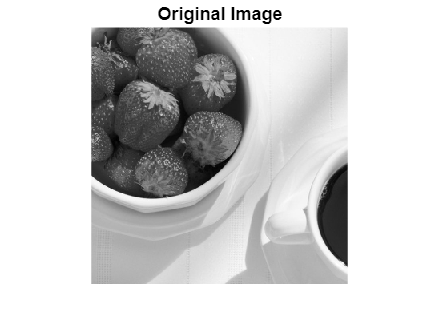


% Display original and decoded images
figure;
imshow(img);
title('Original Image');

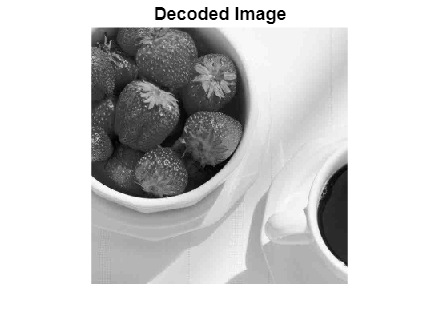

figure;
imshow(uint8(decodedImg));
title('Decoded Image');


[imgBitStream, InterimgPSNR, decodedImg] = InterImgEncoder(img, params);

Not enough input arguments.

Error in Q1_Solution>temporalPrediction (line 222)
    for rowIndex = 1:params.blockSize:nRow

Error in Q1_Solution>blockInterCoding (line 184)
    predictedBlock = temporalPrediction(currentBlock, previousDC, params);

Error in Q1_Solutio


    % Display bitstream and imgPSNR
    disp('imgBitStream:');
    disp(imgBitStream);
    disp('InterimgPSNR:');
    disp(InterimgPSNR);
    
    % Display original and decoded images
    figure;
    imshow(img, []);
    title('Original Image');
    figure;
    imshow(decodedImg, []);
    title('Decoded Image');


function [imgBitStream, imgPSNR, decodedImg] = IntraImgEncoder(img, params)
    % Initialize variables
    img = double(img) - 128;
    previousDC = 0;
    imgBitStream = [];
    decodedFrameBuffer = zeros(size(img));

    % Get image size
    [nRow, nCol] = size(img);

    % Perform block-based intra coding
    for rowIndex = 1:params.blockSize:nRow
        for colIndex = 1:params.blockSize:nCol
            

            % Extract the current block
             currentBlock = img(rowIndex:rowIndex+params.blockSize-1, colIndex:colIndex+params.blockSize-1);

            % Perform block intra coding
            [blockRate, blockimgPSNR, blockBitStream, decodedBlock] = blockIntraCoding(currentBlock, previousDC, params);

            % Update decoded frame buffer
            decodedFrameBuffer(rowIndex:rowIndex+params.blockSize-1, colIndex:colIndex+params.blockSize-1) = decodedBlock;
            % Append block bitstream to the overall image bitstream
            imgBitStream = [imgBitStream, blockBitStream];
            % Update previous DC value
            previousDC = decodedBlock(1,1);
           
        end
    end
    
    % Add 128 to the decoded frame buffer
    decodedImg = decodedFrameBuffer + 128;

    % Compute overall bitstream rate
    bitstreamRate = numel(imgBitStream);

    % Compute overall imgPSNR
    mse = mean((img(:) - double(decodedImg(:))).^2);
    
    imgPSNR = 10 * log10((255*255) / mse);
   
end

function [blockRate, blockimgPSNR, blockBitStream, decodedBlock] = blockIntraCoding(currentBlock, previousDC, params)
    % Perform DCT on the block
    dctBlock = dct2(currentBlock);

    % Quantize the DCT coefficients
    quantizedDctBlock = round(dctBlock / params.quantizationStep);
     
    % Encode the quantized coefficients using entropy coding
    bits = block_entropy_coding(quantizedDctBlock, previousDC);
    blockBitStream = bits;
    

    % Decode the block by inverse quantization and inverse DCT
    decodedQuantizedDctBlock = quantizedDctBlock * params.quantizationStep;
    decodedBlock = idct2(decodedQuantizedDctBlock);
    
    % Compute block bitstream rate
    blockRate = numel(blockBitStream);
    
    % Compute block imgPSNR
    mse = mean((currentBlock(:) - double(decodedBlock(:))).^2);
    
    blockimgPSNR = 10 * log10((255*255) / mse);
end

function decodedBlock = blockIntraDecoding(blockBitStream, previousDC, params)
    % Perform decoding for block-based intra coding

    % Decode the entropy-coded block bitstream
    quantizedDctBlock = block_entropy_decoding(blockBitStream, previousDC);

    % Inverse quantization of the DCT coefficients
    decodedQuantizedDctBlock = quantizedDctBlock * params.quantizationStep;

    % Apply inverse DCT to the dequantized block
    decodedBlock = idct2(decodedQuantizedDctBlock);
end




function [imgBitStream, imgPSNR, decodedImg] = InterImgEncoder(img, params)
    % Initialization
    img = double(img) - 128;
    previousDC = 0;
    imgBitStream = [];
    decodedFrameBuffer = zeros(size(img));

    % Get image size
    [nRow, nCol] = size(img);


    % Perform block-based inter coding
    for rowIndex = 1:params.blockSize:nRow
        for colIndex = 1:params.blockSize:nCol
            % Extract the current block
            currentBlock = img(rowIndex:rowIndex+params.blockSize-1, colIndex:colIndex+params.blockSize-1);

            % Perform block inter coding
            [blockRateIntra, blockPSNRIntra, blockBitStreamIntra] = blockIntraCoding(currentBlock, previousDC, params);
            [blockRateInter, blockPSNRInter, blockBitStreamInter] = blockInterCoding(currentBlock, previousDC, params);

            % Compute IntraCost and InterCost
            IntraCost = blockPSNRIntra + params.lambda * blockRateIntra;
            InterCost = blockPSNRInter + params.lambda * blockRateInter;

            if IntraCost < InterCost
                % Encode a mode flag
                imgBitStream = [imgBitStream, blockBitStreamIntra];
                decodedBlock = blockIntraDecoding(blockBitStreamIntra, previousDC);
            else
                imgBitStream = [imgBitStream, blockBitStreamInter];
                decodedBlock = blockInterDecoding(blockBitStreamInter, previousDC);
            end

            % Update decoded frame buffer
            decodedFrameBuffer(rowIndex:rowIndex+params.blockSize-1, colIndex:colIndex+params.blockSize-1) = decodedBlock;

            % Update previous DC value
            previousDC = decodedBlock(1, 1);
        end
    end

    % Add 128 to the decoded frame buffer
    decodedImg = decodedFrameBuffer + 128;

    % Compute overall bitstream rate
    bitstreamRate = numel(imgBitStream);

    % Compute overall imgPSNR
    mse = mean((img(:) - double(decodedImg(:))).^2);
    imgPSNR = 10 * log10((255*255) / mse);
end


function [blockRate, blockPSNR, blockBitStream, decodedBlock] = blockInterCoding(currentBlock, previousDC, params)
    % Predict the current block using temporal prediction (INTER mode)
    predictedBlock = temporalPrediction(currentBlock, previousDC, params);

    % Compute the residual block by subtracting the predicted block
    residualBlock = currentBlock - predictedBlock;

    % Apply transform to the residual block (e.g., DCT)
    transformedBlock = dct2(residualBlock);

    % Quantize the transformed block
    quantizedBlock = round(transformedBlock / params.quantizationStep);

    % Encode the quantized block using entropy coding (e.g., Exp-Golomb coding)
    blockBitStream = expGolombSigned(quantizedBlock(:));
    blockRate = numel(blockBitStream);

    % Decode the quantized block using entropy decoding
    decodedQuantizedBlock = expGolombSignedDecode(blockBitStream);

    % Dequantize the decoded quantized block
    dequantizedBlock = decodedQuantizedBlock * params.quantizationStep;

    % Apply inverse transform to the dequantized block (e.g., inverse DCT)
    decodedBlock = idct2(dequantizedBlock);

    % Add the predicted block to the decoded block
    decodedBlock = decodedBlock + predictedBlock;

    % Compute block PSNR
    mse = mean((currentBlock(:) - double(decodedBlock(:))).^2);
    blockPSNR = 10 * log10((255*255) / mse);
end

function predictedBlock = temporalPrediction(currentBlock, previousDC, blockSize, radius, lambda, params)

    % Perform temporal prediction using meReg
    [nRow, nCol] = size(currentBlock);
    predictedBlock = zeros(size(currentBlock));

    for rowIndex = 1:params.blockSize:nRow
        for colIndex = 1:params.blockSize:nCol
            % Extract the current block
            B = currentBlock(rowIndex:rowIndex+params.blockSize-1, colIndex:colIndex+params.blockSize-1);

            % Perform motion estimation using meReg
            refBlock = previousDC(rowIndex:rowIndex+params.blockSize-1, colIndex:colIndex+params.blockSize-1);
            mvf = meReg(B, refBlock, params.blockSize, params.blockSize, params.radius, params.lambda);

            % Extract the motion vectors
            motionVectorsRow = mvf(:,:,1);
            motionVectorsCol = mvf(:,:,2);

            % Predict the block using motion vectors
            predictedBlock(rowIndex:rowIndex+params.blockSize-1, colIndex:colIndex+params.blockSize-1) = ...
                motionCompensation(refBlock, motionVectorsRow, motionVectorsCol, params.blockSize, params.blockSize);
        end
    end
end

function motionCompensatedBlock = motionCompensation(refBlock, motionVectorsRow, motionVectorsCol, blockSizeRow, blockSizeCol)
    % Perform motion compensation for a block

    [nRow, nCol] = size(refBlock);
    motionCompensatedBlock = zeros(size(refBlock));

    for rowIndex = 1:nRow
        for colIndex = 1:nCol
            deltaRow = motionVectorsRow(rowIndex, colIndex);
            deltaCol = motionVectorsCol(rowIndex, colIndex);

            % Calculate the corresponding position in the reference block
            refRowIndex = rowIndex + deltaRow;
            refColIndex = colIndex + deltaCol;

            % Perform motion compensation if the reference position is valid
            if (refRowIndex >= 1 && refRowIndex <= nRow) && (refColIndex >= 1 && refColIndex <= nCol)
                motionCompensatedBlock(rowIndex, colIndex) = refBlock(refRowIndex, refColIndex);
            end
        end
    end
end

function decodedBlock = blockInterDecoding(blockBitStream, previousDC, params)
    % Perform decoding for block-based inter coding

    % Decode the entropy-coded block bitstream
    quantizedBlock = expGolombSignedDecode(blockBitStream);

    % Dequantize the decoded quantized block
    dequantizedBlock = quantizedBlock * params.quantizationStep;

    % Apply inverse transform to the dequantized block (e.g., inverse DCT)
    decodedBlock = idct2(dequantizedBlock);

    % Apply temporal prediction (INTER mode)
    predictedBlock = temporalPrediction(decodedBlock, previousDC, params);

    % Add the predicted block to the decoded block
    decodedBlock = decodedBlock + predictedBlock;
end

function N = expGolombSignedDecode(bits)
    if bits(1) == 0
        N = expGolombUnsignedDecode(bits(2:end)) / 2 + 1;
    elseif bits(1) == 1
        N = -(expGolombUnsignedDecode(bits(2:end)) / 2);
    else
        error('Invalid bit sequence');
    end
end